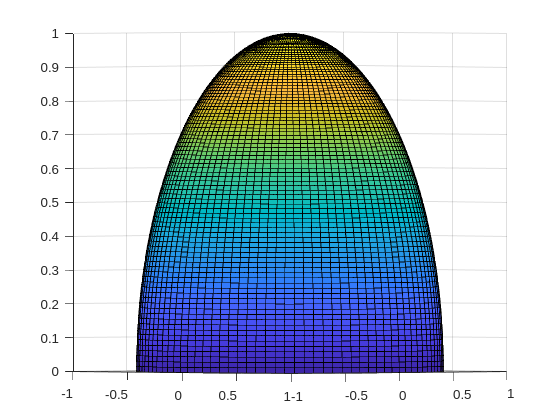

clear;clc;
%Obter as coodernadas esféricas do ponto P(1,1,1)
%R=sqrt(1^2+1^2+1^2)=sqrt(3)
%theta=pi/4 -> ângulo da projeção ao eixo XX
%phi=acos(sqrt(3)/3) -> ângulo da reta que une O a P ao eixo ZZ

%azimuth=pi/4; %theta
azimuth=linspace(0,2*pi);

%elevation=acos(sqrt(2/3)); %semelhante a phi

%elevation=atan(1/sqrt(2));

%elevation=acos(sqrt(3)/3); %phi
%elevation=pi/2-elevation; %complementar do ângulo anterior
%elevation=linspace(-pi/2,pi/2); %equivalente ao phi

elevation=linspace(0,pi/2); %equivalente ao phi

%R=sqrt(3);
R=1;

[azimuth, elevation]=meshgrid(azimuth,elevation);

[x,y,z]=sph2cart(azimuth, elevation, R);

surf(x,y,z);